# Pràctica 6. Exercici 1

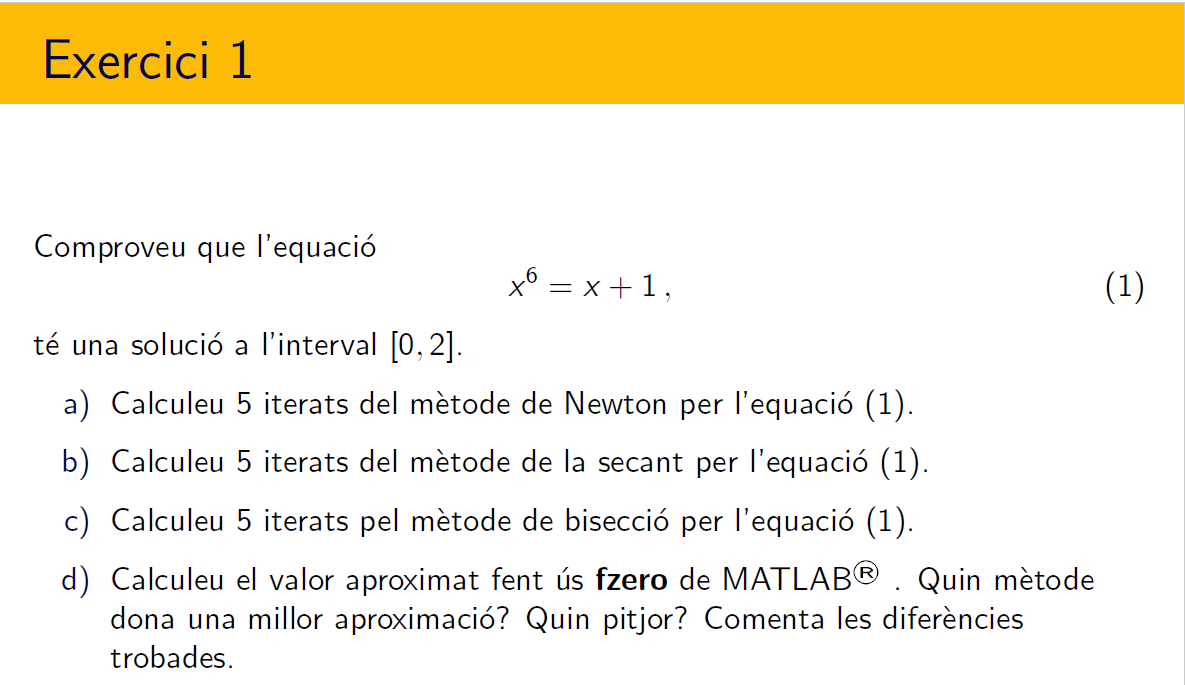

================================================================================

- `Comproveu que l'equació té una solució a l'interval `$[0,2]$

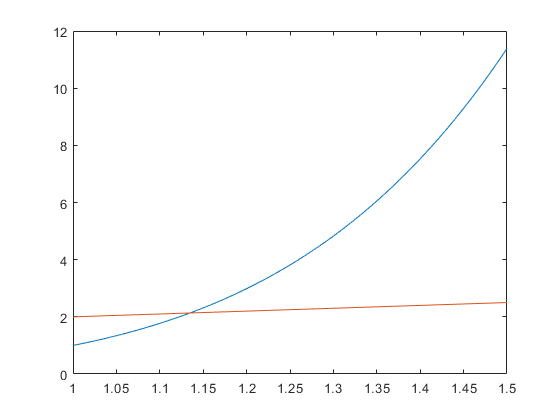

t = linspace(1,1.5);
plot(t,t.^6,t,t+1)

f = @(x) x.^6-x-1;
t = (1:0.1:1.5)';
disp([t,f(t)])

    1.0000   -1.0000
    1.1000   -0.3284
    1.2000    0.7860
    1.3000    2.5268
    1.4000    5.1295
    1.5000    8.8906



- `Calculeu 5 iterats del mètode de Newton`

f = @(x) x.^6-x-1;
fp = @(x) 6*x.^5-1;
a = 1.1; b = 1.2; n = 5; tol = eps;
newton(f,fp,a,tol,n)

    k          x                   f                   l
    0   1.100000000000000  -0.328438999999999                    
    1   1.137912585160440   0.033055325417891   0.037912585160440
    2   1.134748520270514   0.000250846401163   0.003164064889926
    3   1.134724139838480   0.000000014782916   0.000024380432034
    4   1.134724138401519  -0.000000000000001   0.000000001436961
    5   1.134724138401519  -0.000000000000001   0.000000000000000


ans =        1.1347


- `Calculeu 5 iterats del mètode de la secant`

f = @(x) x.^6-x-1;
a = 1.1; b = 1.2; n = 5; tol = eps;
secant(f,a,b,tol,tol,n)

    k          x                   f                   l
        1.100000000000000  -3.284389999999993e-01                    
        1.200000000000000   7.859839999999993e-01                    
    1   1.129471663811677  -5.335363960159545e-02   0.070528336188323
    2   1.133954893507509  -7.899003471724564e-03   0.004483229695833
    3   1.134733978985847   1.012386866792170e-04   0.000779085478338
    4   1.134724120085445  -1.884289710929465e-07   0.000009858900403
    5   1.134724138401084  -4.482636484226532e-12   0.000000018315639


ans =        1.1347


- `Calculeu 5 iterats del mètode de la bisecció`

f = @(x) x.^6-x-1;
a = 1.1; b = 1.2; n = 5; tol = eps;
bisect(f,a,b,n,tol)

    k          x                   f                   l
        1.100000000000000  -0.328438999999999                    
        1.200000000000000   0.785983999999999                    
    1   1.150000000000000   0.163060765624999   0.050000000000000
    2   1.125000000000000  -0.097713470458984   0.025000000000000
    3   1.137500000000000   0.028749282993316   0.012500000000000
    4   1.131250000000000  -0.035441712911068   0.006250000000000
    5   1.134375000000000  -0.003588776076577   0.003125000000000
        1.135937500000000   0.012519278729156   0.001562500000000


ans =        1.1359


- `Calculeu el valor aproximat fent ús de ``zeroin/fzero`` de MATLAB®`

f = @(x)x.^6-x-1;
a = 1.1; b =1.2; 
zeroin(f,a,b)

    1  initial   1.100000000000000  -3.284389999999993e-01
    2  initial   1.200000000000000   7.859839999999993e-01
    3  secant    1.129471663811677  -5.335363960159545e-02
    4  secant    1.135187782354627   4.775145694130734e-03
    5  secant    1.134718216395032  -6.092253217615529e-05
    6  secant    1.134724131768005  -6.824313314446329e-08
    7  secant    1.134724138401614   9.769962616701378e-13
    8  secant    1.134724138401519  -8.881784197001252e-16
    9  minimal   1.134724138401520   1.554312234475219e-15


ans =        1.1347


options = optimset('Display','iter'); % show iterations
[x fval exitflag output] = fzero(f,[a,b],options)

 
 Func-count    x          f(x)             Procedure
    2             1.1     -0.328439        initial
    3         1.12947    -0.0533536        interpolation
    4         1.13482    0.00103201        interpolation
    5         1.13472  -1.31843e-05        interpolation
    6         1.13472  -3.19599e-09        interpolation
    7         1.13472  -8.88178e-16        interpolation
    8         1.13472  -8.88178e-16        interpolation
 
Zero found in the interval [1.1, 1.2]


x =        1.1347


fval =   -8.8818e-16


exitflag =      1


output = struct with fields:
    intervaliterations: 0
            iterations: 6
             funcCount: 8
             algorithm: 'bisection, interpolation'
               message: 'Zero found in the interval [1.1, 1.2]'


[x fval exitflag output] = fzero(f,1,options)

 
Search for an interval around 1 containing a sign change:
 Func-count    a          f(a)             b          f(b)        Procedure
    1               1            -1             1            -1   initial interval
    3        0.971716      -1.12986       1.02828     -0.846116   search
    5            0.96      -1.17724          1.04     -0.774681   search
    7        0.943431      -1.23831       1.05657      -0.66538   search
    9            0.92      -1.31364          1.08     -0.493126   search
   11        0.886863       -1.4003       1.11314     -0.210781   search
   13            0.84       -1.4887          1.16      0.276396   search
 
Search for a zero in the interval [0.84, 1.16]:
 Func-count    x          f(x)             Procedure
   13            1.16      0.276396        initial
   14         1.10989     -0.240576        interpolation
   15         1.13321    -0.0155237        interpolation
   16         1.13473   8.66586e-05        interpolation
   17         1.13

x =        1.1347


fval =   -8.8818e-16


exitflag =      1


output = struct with fields:
    intervaliterations: 6
            iterations: 7
             funcCount: 20
             algorithm: 'bisection, interpolation'
               message: 'Zero found in the interval [0.84, 1.16]'


- `Quin mètode dona una millor aproximació? Quin pitjor? Comenta les diferències trobades.`

% Cal observar i comentar l'ordre de convergència dels tres mètodes.

